# **Report 1**

## **Pouya Abginechi - 40023001**

## **Alisina Shahmohammadi - 40023041**

#### **1. Stem and Plot Command:**

showing a Sine with plot and stem built-in functions of MatLab.

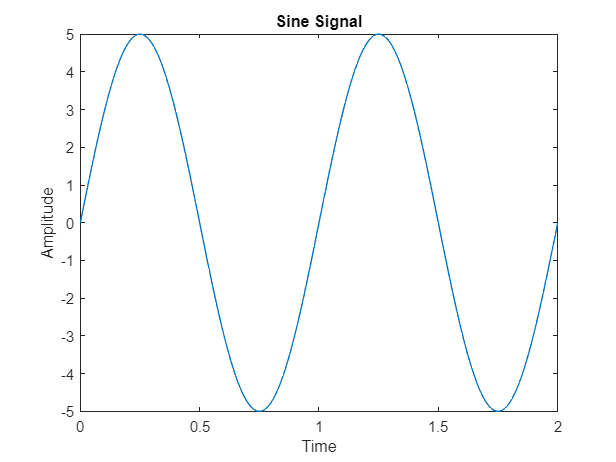

t = 0:0.01:2;
x = 5*sin(2*pi*(t));
plot(t,x);
title("Sine Signal");
xlabel("Time");
ylabel("Amplitude");

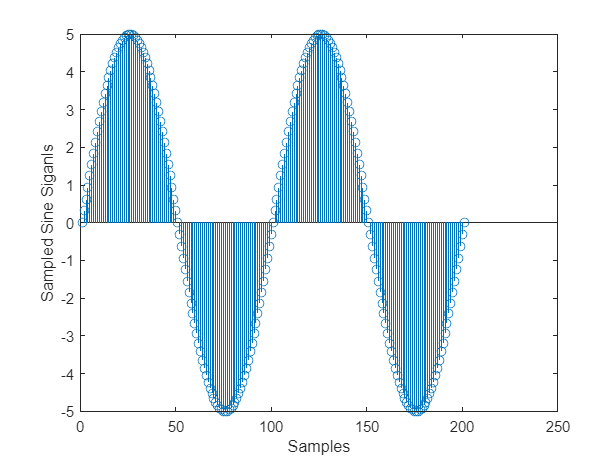

stem(x);
xlabel("Samples");
ylabel("Sampled Sine Siganls");

#### **2.Subplot Command:**

Then we define a random signal (noise) and add it to the sinusoidal signal we defined in the previous section. Then, we display the result using the **subplot** command.

noise = 2*rand(1,length(t))-1;
noisysignal=noise + x;
figure;
subplot(2,1,1);
plot(t,x);
subplot(2,1,2);
plot(t,noisysignal);

#### **3.Conv Command:**

Then, we pass the noisy signal through a moving average filter.

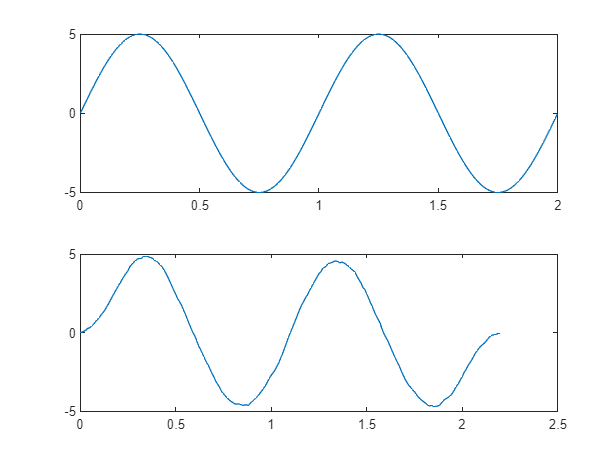

movingaverage = ones(1,21)/21;
convolution = conv(noisysignal,movingaverage);
Ts=0.01;
t_conv = linspace(t(1), t(1) + Ts * (length(convolution) - 1), length(convolution));
plot (t_conv,convolution);

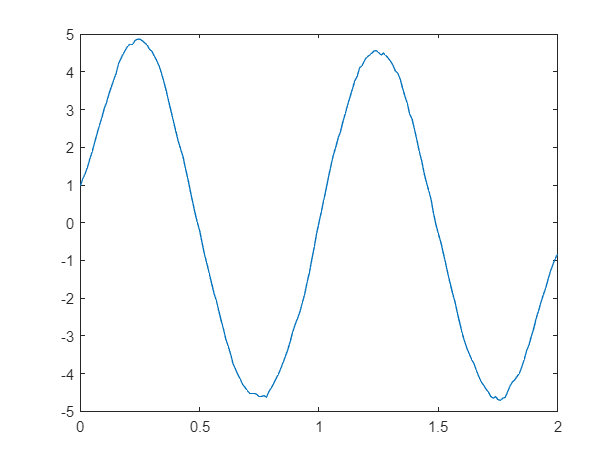


convolvedsignal = conv(noisysignal,movingaverage,'same');
figure;
plot(t,convolvedsignal);
hold on;

#### **4.Filter Command:**

Applying the same approach, but this time using the **filter()** function instead of **conv()**.

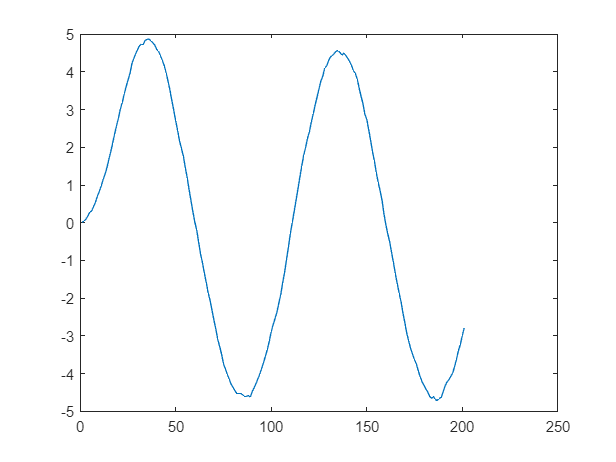

movingaverage = ones(1,21)/21;
filteredsignal = filter(movingaverage,1,noisysignal);

figure;
plot(1:length(filteredsignal),filteredsignal);
hold on;

#### **5.Defining Function:**

Then, we create **singen(w, n)** and resample it to observe the given result.

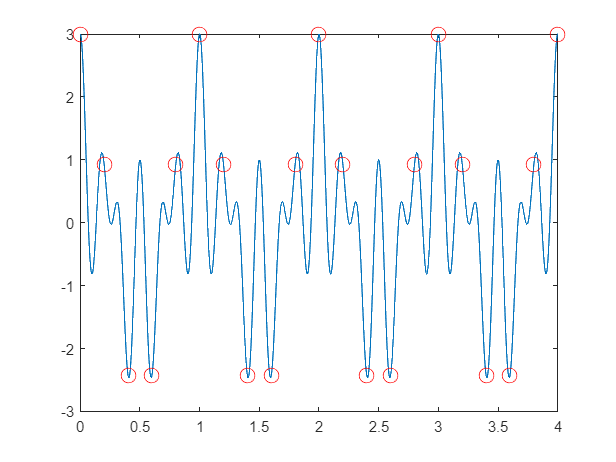

f1 = 1000;    
f2 = 4000;    
f3 = 6000;    
Fs = 5000;   
t_start = 0;  
t_end = 0.004;  
dt = 1/(100 * f3); 


t_continuous = t_start:dt:t_end;


x_continuous = cos(2*pi*f1*t_continuous) + cos(2*pi*f2*t_continuous) + cos(2*pi*f3*t_continuous);


figure;
plot(t_continuous*1000, x_continuous); 
hold on;


t_sampled = t_start:1/Fs:t_end;


x_sampled = cos(2*pi*f1*t_sampled) + cos(2*pi*f2*t_sampled) + cos(2*pi*f3*t_sampled);


plot(t_sampled*1000, x_sampled, 'ro','MarkerSize',10);


t_reconstructed = t_continuous;
x_reconstructed = sinc_interp(x_sampled, t_sampled, t_reconstructed, Fs);

Unrecognized function or variable 'sinc_interp'.



plot(t_reconstructed*1000, x_reconstructed, 'g--');
plot(t_reconstructed*1000, x_reconstructed, 'ko');


grid on;
hold off;